#               Computational Electromagnetics 

##                           Sadiku-CHap3-Figure-3.21

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1401/08/18             

Finite Difference Method :::::     Figure 3.21 of Sadiku 4th edition

This Program calculates the characterisitic impedance of the transmission line shown in Figure 3.14!

clear; clc; close all; format compact;

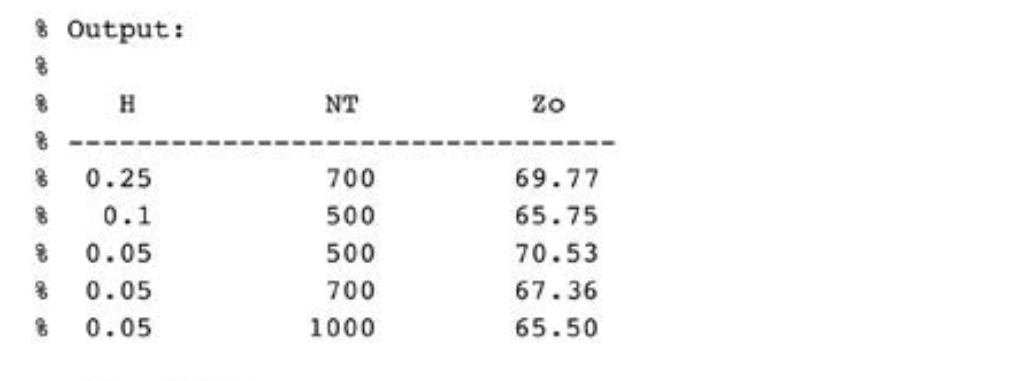

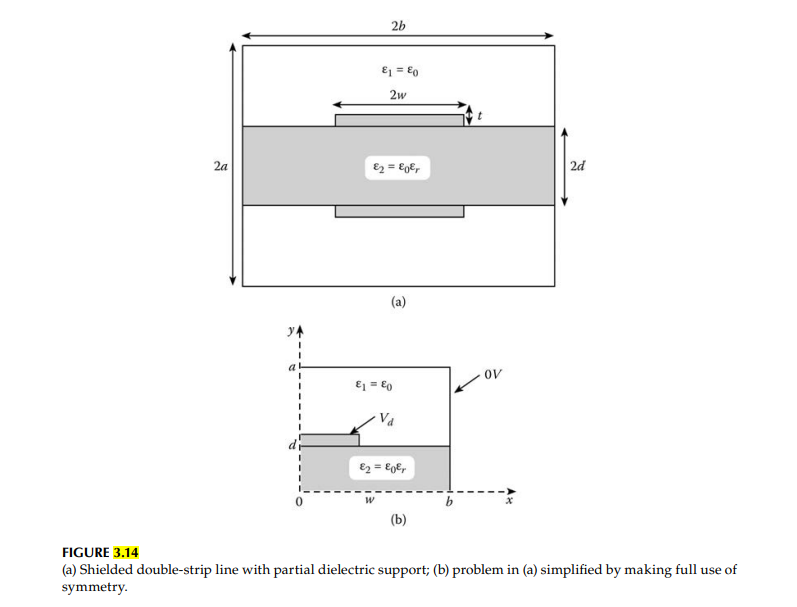

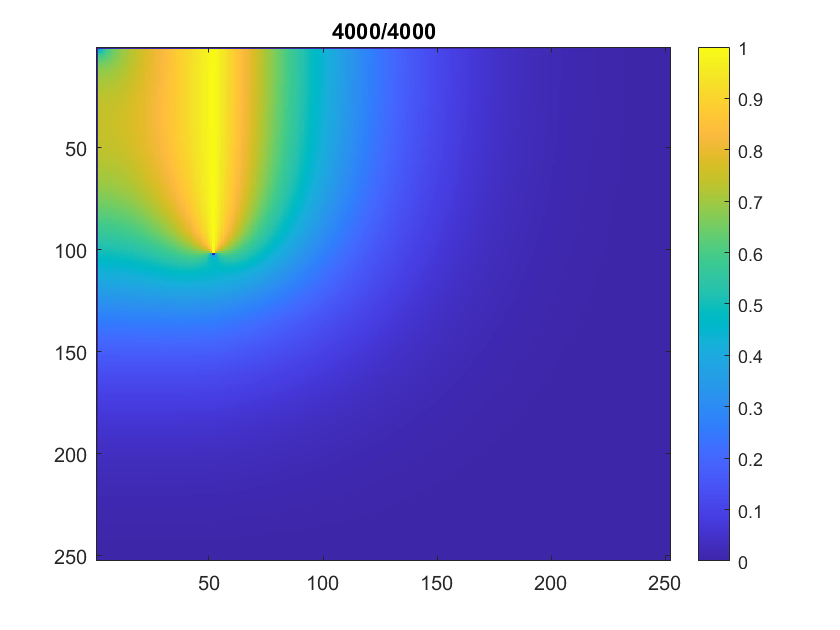

H = 0.01; 
NT = 4000;

A  = 2.5; B=2.5; D=0.5; W=1.0;

ER = 2.35 ;
EO = 8.81e-12;
U = 3.0e+8;

NX  = A/H;
NY  = B/H;
ND  = D/H;
NW  = W/H;
VD  = 1.0;

% Calculate charge with and without DIELECTRIC

ERR = 1.0;
for L=1:2
    E1 = EO;
    E2 = EO*ERR;


% INITIALIZATION

    V = zeros(NX+2,NY+2);

% Set POTENTIAL ON INNER CONDUCTOR (FIXED NODES) EQUAL TO VD
    V(2:NW+1,ND+2)  =VD;

% CALCULATE POTENTIAL AT FREE NODES

    P1 = E1/(2*(E1+E2));
    P2 = E2/(2*(E1+E2));
    for K=1:NT
        for I=0:NX-1
            for J=0:NY-1
                if( (J==ND)&(I<=NW)  )
                    % do nothing
                elseif (J==ND)
                    % IMPOSE BOUNDARY Condition at the Interface
                    V(I+2,J+2) = 0.25*( V(I+3,J+2) +  V(I+1,J+2)   )  + P1*V(I+2,J+3) + P2*V(I+2,J+1);
                elseif (I==0)
                    % IMPOSE Symmetry COndition Along with Y-AXIS
                    V(I+2,J+2) = ( 2*V(I+3,J+2) + V(I+2,J+3) + V(I+2,J+1)   )/4.0;
                elseif (J==0)
                    % IMPOSE Symmetry COndition Along with X-AXIS
                    V(I+2,J+2) = ( V(I+3,J+2) + V(I+1,J+2) + 2*V(I+2,J+3)   )/4.0;
                else 
                    V(I+2,J+2) = (  V(I+3,J+2) + V(I+1,J+2) + V(I+2,J+3) + V(I+2,J+1) )/4.0;
                end
            end
        end
        % ANimation of Calculation
        figure(1);
        imagesc(V);
        colorbar;
        title([num2str(K),'/' , num2str(NT) ])
        drawnow


    end

% Now Calculate the TOTAL CHARGE ENCLOSED IN A Rectangular Path Surrounding the Inner CONDUCTOR:
    IOUT = round((NX+NW)/2) ;
    JOUT = round((NY+ND)/2) ;
% SUM Potential on Inner and Outer LOOPS:
    for K=1:2
        SUM = E1* sum( V(3:IOUT+1 , JOUT+2)  )  + E1*V(2,JOUT+2)/2 + E2*V(IOUT+2,2)/2;
        for J=1:JOUT-1
            if(J<ND)
                SUM =SUM + E2*V(IOUT+2,J+2);
            elseif (J==ND)
                SUM = SUM + (E1+E2)*V(IOUT+2,J+2)/2;
            else 
                SUM = SUM + E1*V(IOUT+2,J+2);
            end
        end
        if K==1
            SV(1) = SUM;
        end
        IOUT = IOUT -1;
        JOUT = JOUT -1;
    end
    SUM  = SUM + 2.0* E1* V(IOUT+2,JOUT+2);
    SV(2) =     SUM;
    Q(L)  = abs(SV(1) - SV(2) );
    ERR = ER;
 end



 % Calculate the Z0:
    C0 = 4.0*Q(1)/VD ;
    C1 = 4.0*Q(2)/VD;
    Z0 = 1.0/( U*sqrt(C0*C1) );

    disp([H,NT,Z0]);

   1.0e+03 *
    0.0000    4.0000    0.1266
